%% PREPARATION: Read CSV File and Compute Basic Statistics
filename = 'Uniform - with Artillery/IrpinModel Vary Site-Selection Artillery Active-table.csv';
data = readtable(filename);

disp(head(data))

    x_runNumber_    turn_on_artillery_    turn_on_stop_conditions_      site_selection_mode      x_step_    battle_outcome    total_infantry_crossed    total_infantry_casualties_10    total_infantry_used    ticks
    ____________    __________________    ________________________    _______________________    _______    ______________    ______________________    ____________________________    ___________________    _____

          1              {'true'}                 {'true'}            {'01 Shortest Bridges'}     10120      {'Retreat'}                0                           4510                       5590            10120
          2         

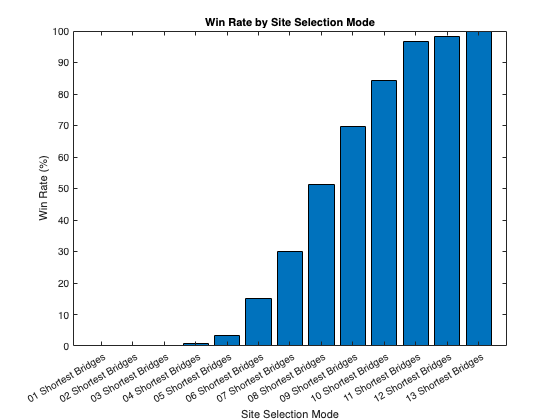


% Get unique site selection modes and battle outcomes
siteModes = unique(data.site_selection_mode);
battleOutcomes = unique(data.battle_outcome);

% Calculate win rate (percentage of 'Victory') for each site selection mode
winRate = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    winRate(i) = sum(strcmp(data.battle_outcome(idx), 'Victory')) / sum(idx) * 100;
end

% Calculate casualty rate for each site selection mode
% Casualty Rate = (Total Infantry Casualties (10) / Total Infantry Used) * 100
casualtyRate = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    casualtyRate(i) = sum(data.total_infantry_casualties_10(idx)) / sum(data.total_infantry_used(idx)) * 100;
end

% Calculate row-wise casualty rate (for each observation)
rowCasualtyRate = (data.total_infantry_casualties_10 ./ data.total_infantry_used) * 100;

% Sort data by ticks (using ticks as the time variable)
[sortedTicks, sortIdx] = sort(data.ticks);
sortedUsed = data.total_infantry_used(sortIdx);
sortedCrossed = data.total_infantry_crossed(sortIdx);
sortedCasualties = data.total_infantry_casualties_10(sortIdx);
cumUsed = cumsum(sortedUsed);
cumCrossed = cumsum(sortedCrossed);
cumCasualties = cumsum(sortedCasualties);

% Calculate mean and median values of key metrics for each site selection mode
meanUsed = zeros(length(siteModes),1);
medianUsed = zeros(length(siteModes),1);
meanCrossed = zeros(length(siteModes),1);
medianCrossed = zeros(length(siteModes),1);
meanCasualties = zeros(length(siteModes),1);
medianCasualties = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    meanUsed(i) = mean(data.total_infantry_used(idx));
    medianUsed(i) = median(data.total_infantry_used(idx));
    meanCrossed(i) = mean(data.total_infantry_crossed(idx));
    medianCrossed(i) = median(data.total_infantry_crossed(idx));
    meanCasualties(i) = mean(data.total_infantry_casualties_10(idx));
    medianCasualties(i) = median(data.total_infantry_casualties_10(idx));
end

% Calculate summed values (for stacking purposes) for each site selection mode
sumUsed = zeros(length(siteModes),1);
sumCrossed = zeros(length(siteModes),1);
sumCasualties = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    sumUsed(i) = sum(data.total_infantry_used(idx));
    sumCrossed(i) = sum(data.total_infantry_crossed(idx));
    sumCasualties(i) = sum(data.total_infantry_casualties_10(idx));
end

%% FIGURE 1: Bar Graph of Win Rate by Site Selection Mode
figure;
bar(categorical(siteModes), winRate);
xlabel('Site Selection Mode');
ylabel('Win Rate (%)');
title('Win Rate by Site Selection Mode');

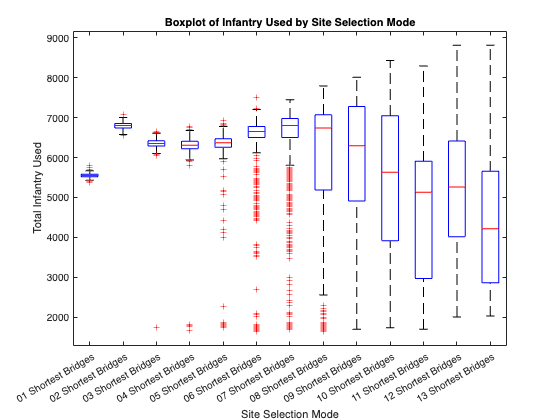


%% FIGURE 2: Boxplot of Total Infantry Used by Site Selection Mode
figure;
boxplot(data.total_infantry_used, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Used');
title('Boxplot of Infantry Used by Site Selection Mode');

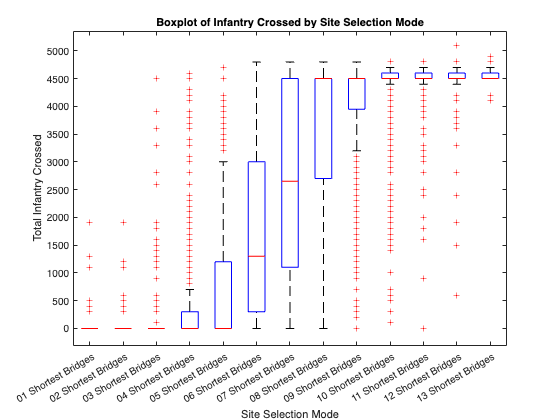


%% FIGURE 3: Boxplot of Total Infantry Crossed by Site Selection Mode
figure;
boxplot(data.total_infantry_crossed, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Crossed');
title('Boxplot of Infantry Crossed by Site Selection Mode');

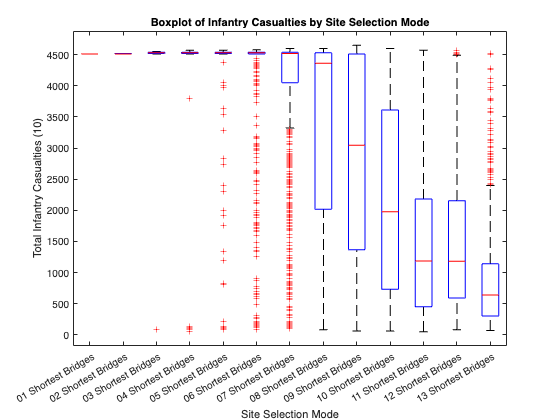


%% FIGURE 4: Boxplot of Total Infantry Casualties (10) by Site Selection Mode
figure;
boxplot(data.total_infantry_casualties_10, data.site_selection_mode);
xlabel('Site Selection Mode');
ylabel('Total Infantry Casualties (10)');
title('Boxplot of Infantry Casualties by Site Selection Mode');

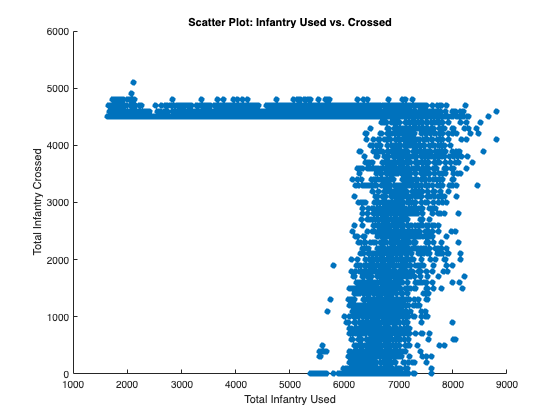


%% FIGURE 5: Scatter Plot - Infantry Used vs. Infantry Crossed
figure;
scatter(data.total_infantry_used, data.total_infantry_crossed, 'filled');
xlabel('Total Infantry Used');
ylabel('Total Infantry Crossed');
title('Scatter Plot: Infantry Used vs. Crossed');

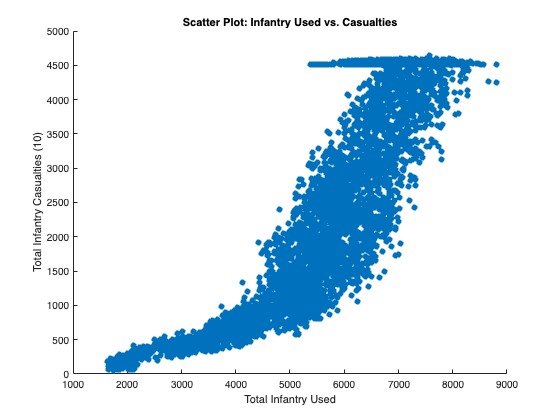


%% FIGURE 6: Scatter Plot - Infantry Used vs. Infantry Casualties (10)
figure;
scatter(data.total_infantry_used, data.total_infantry_casualties_10, 'filled');
xlabel('Total Infantry Used');
ylabel('Total Infantry Casualties (10)');
title('Scatter Plot: Infantry Used vs. Casualties');

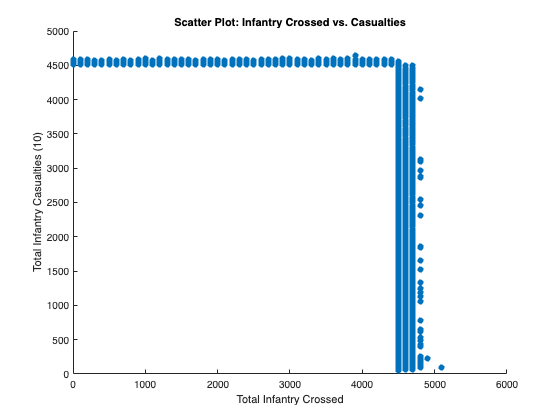


%% FIGURE 7: Scatter Plot - Infantry Crossed vs. Infantry Casualties (10)
figure;
scatter(data.total_infantry_crossed, data.total_infantry_casualties_10, 'filled');
xlabel('Total Infantry Crossed');
ylabel('Total Infantry Casualties (10)');
title('Scatter Plot: Infantry Crossed vs. Casualties');

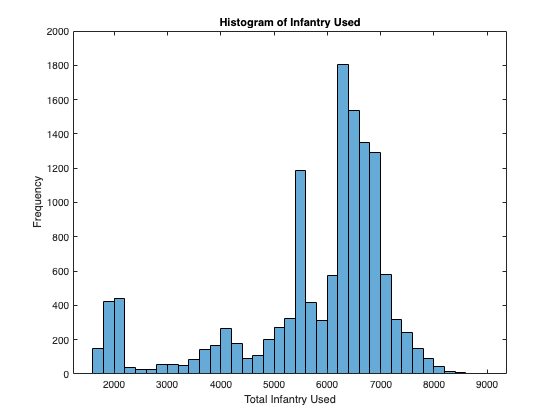


%% FIGURE 8: Histogram of Total Infantry Used
figure;
histogram(data.total_infantry_used);
xlabel('Total Infantry Used');
ylabel('Frequency');
title('Histogram of Infantry Used');

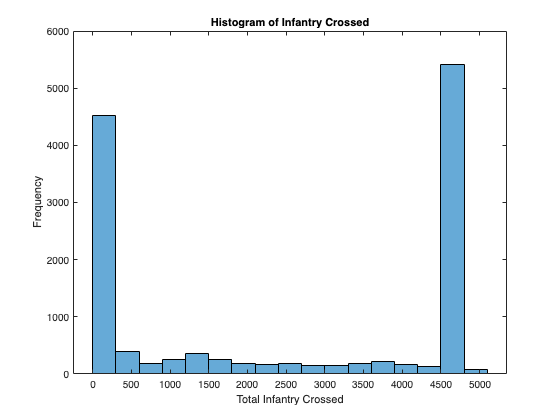


%% FIGURE 9: Histogram of Total Infantry Crossed
figure;
histogram(data.total_infantry_crossed);
xlabel('Total Infantry Crossed');
ylabel('Frequency');
title('Histogram of Infantry Crossed');

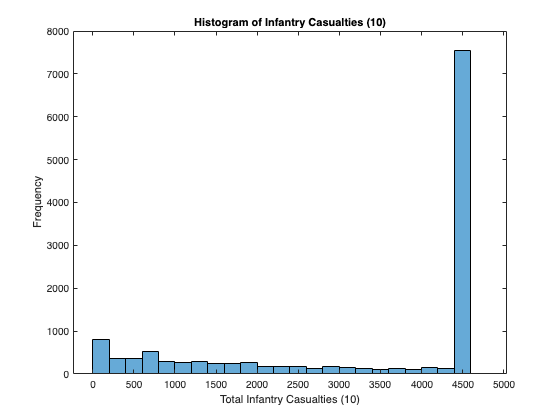


%% FIGURE 10: Histogram of Total Infantry Casualties (10)
figure;
histogram(data.total_infantry_casualties_10);
xlabel('Total Infantry Casualties (10)');
ylabel('Frequency');
title('Histogram of Infantry Casualties (10)');

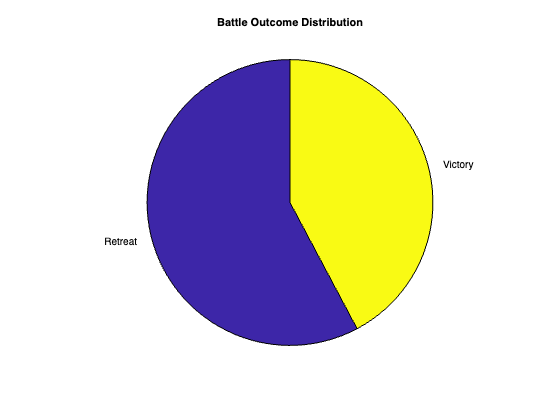


%% FIGURE 11: Pie Chart of Battle Outcome Distribution
figure;
outcomeCounts = zeros(length(battleOutcomes),1);
for i = 1:length(battleOutcomes)
    outcomeCounts(i) = sum(strcmp(data.battle_outcome, battleOutcomes{i}));
end
pie(outcomeCounts, battleOutcomes);
title('Battle Outcome Distribution');

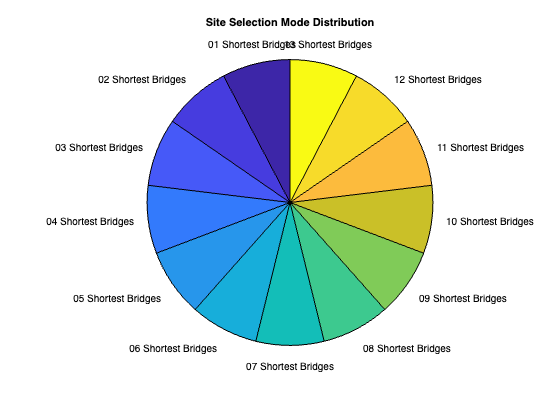


%% FIGURE 12: Pie Chart of Site Selection Mode Distribution
figure;
modeCounts = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    modeCounts(i) = sum(strcmp(data.site_selection_mode, siteModes{i}));
end
pie(modeCounts, siteModes);
title('Site Selection Mode Distribution');

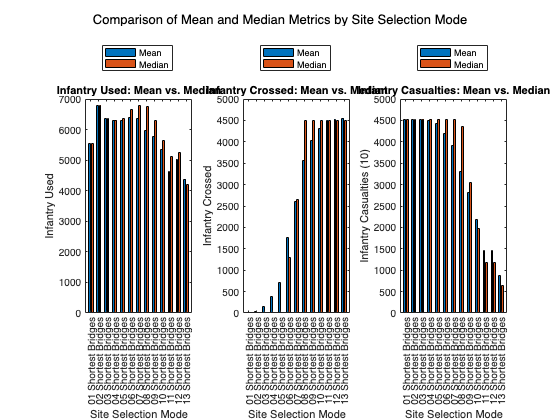


%% FIGURE 13: Grouped Bar Graphs Comparing Mean and Median Metrics by Site Selection Mode
figure;
% Subplot 1: Infantry Used
subplot(1,3,1);
bar(categorical(siteModes), [meanUsed, medianUsed]);
xlabel('Site Selection Mode');
ylabel('Infantry Used');
legend({'Mean','Median'}, 'Location', 'northoutside');
title('Infantry Used: Mean vs. Median');
% Subplot 2: Infantry Crossed
subplot(1,3,2);
bar(categorical(siteModes), [meanCrossed, medianCrossed]);
xlabel('Site Selection Mode');
ylabel('Infantry Crossed');
legend({'Mean','Median'}, 'Location', 'northoutside');
title('Infantry Crossed: Mean vs. Median');
% Subplot 3: Infantry Casualties (10)
subplot(1,3,3);
bar(categorical(siteModes), [meanCasualties, medianCasualties]);
xlabel('Site Selection Mode');
ylabel('Infantry Casualties (10)');
legend({'Mean','Median'}, 'Location', 'northoutside');
title('Infantry Casualties: Mean vs. Median');
sgtitle('Comparison of Mean and Median Metrics by Site Selection Mode');

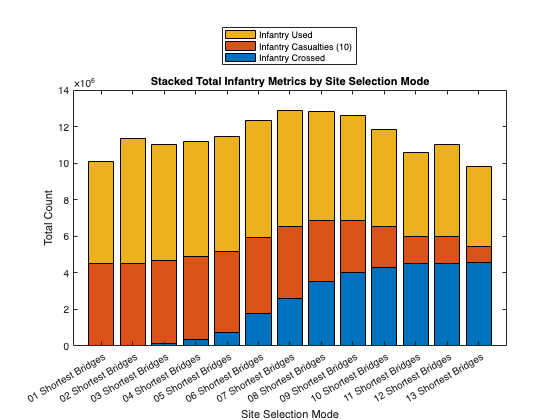


%% FIGURE 14: Stacked Bar Graph of Summed Infantry Metrics by Site Selection Mode
figure;
stackedData = [sumCrossed, sumCasualties, sumUsed];
bar(categorical(siteModes), stackedData, 'stacked');
xlabel('Site Selection Mode');
ylabel('Total Count');
legend({'Infantry Crossed','Infantry Casualties (10)','Infantry Used'}, 'Location', 'northoutside');
title('Stacked Total Infantry Metrics by Site Selection Mode');

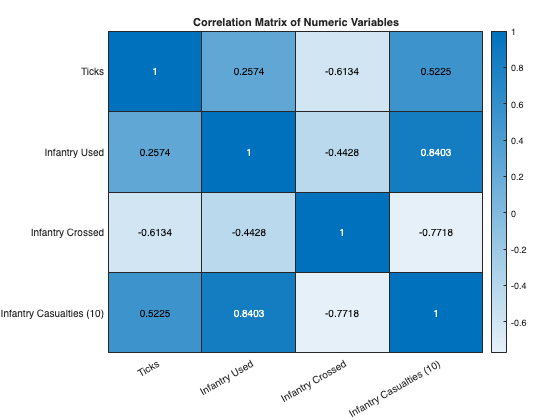


%% FIGURE 15: Heatmap of Correlation Coefficients among Numeric Variables
figure;
vars = [data.ticks, data.total_infantry_used, data.total_infantry_crossed, data.total_infantry_casualties_10];
corrMatrix = corr(vars);
h = heatmap({'Ticks','Infantry Used','Infantry Crossed','Infantry Casualties (10)'}, ...
            {'Ticks','Infantry Used','Infantry Crossed','Infantry Casualties (10)'}, corrMatrix);
h.Title = 'Correlation Matrix of Numeric Variables';

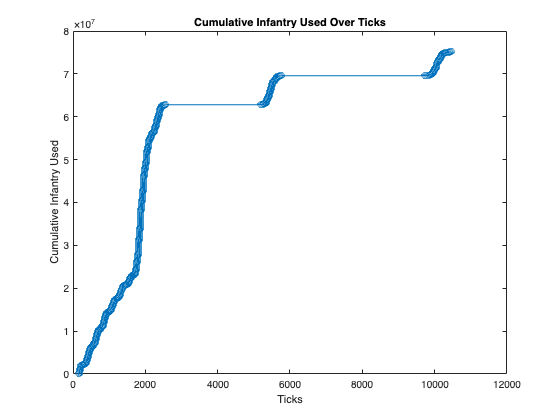


%% FIGURE 16: Line Plot of Cumulative Infantry Used Over Ticks
figure;
plot(sortedTicks, cumUsed, '-o');
xlabel('Ticks');
ylabel('Cumulative Infantry Used');
title('Cumulative Infantry Used Over Ticks');

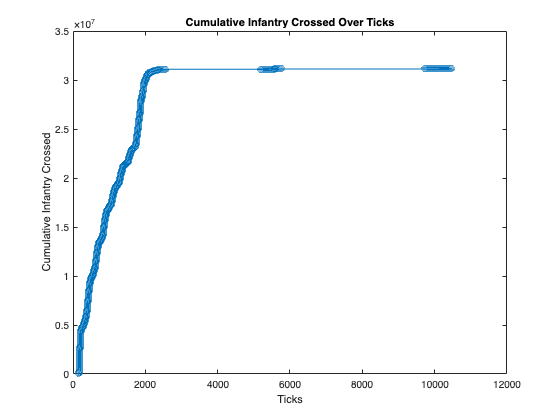


%% FIGURE 17: Line Plot of Cumulative Infantry Crossed Over Ticks
figure;
plot(sortedTicks, cumCrossed, '-o');
xlabel('Ticks');
ylabel('Cumulative Infantry Crossed');
title('Cumulative Infantry Crossed Over Ticks');

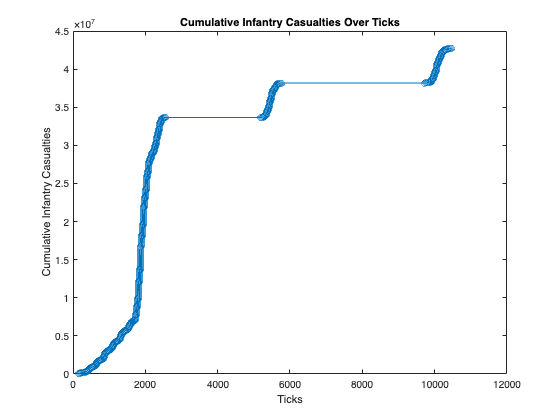


%% FIGURE 18: Line Plot of Cumulative Infantry Casualties Over Ticks
figure;
plot(sortedTicks, cumCasualties, '-o');
xlabel('Ticks');
ylabel('Cumulative Infantry Casualties');
title('Cumulative Infantry Casualties Over Ticks');

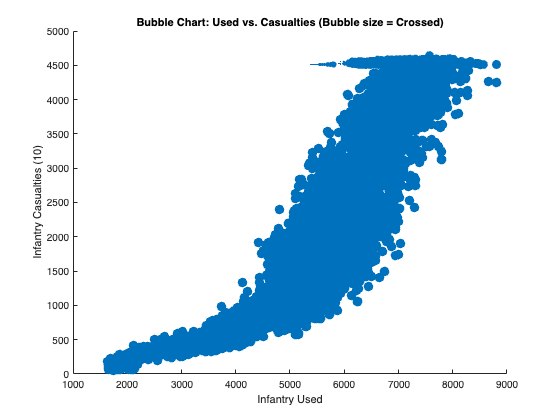


%% FIGURE 19: Bubble Chart - Infantry Used vs. Casualties 
% Bubble size is proportional to Infantry Crossed.
% Ensure bubble sizes are positive:
bubbleSizes1 = 100 * (data.total_infantry_crossed ./ max(data.total_infantry_crossed));
bubbleSizes1(bubbleSizes1 <= 0) = 1;  % Replace zeros or nonpositive values with 1.
figure;
scatter(data.total_infantry_used, data.total_infantry_casualties_10, bubbleSizes1, 'filled');
xlabel('Infantry Used');
ylabel('Infantry Casualties (10)');
title('Bubble Chart: Used vs. Casualties (Bubble size = Crossed)');

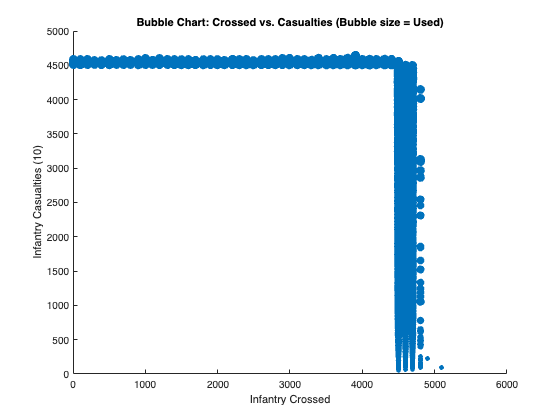


%% FIGURE 20: Bubble Chart - Infantry Crossed vs. Casualties 
% Bubble size is proportional to Infantry Used.
bubbleSizes2 = 100 * (data.total_infantry_used ./ max(data.total_infantry_used));
bubbleSizes2(bubbleSizes2 <= 0) = 1;  % Ensure positive sizes.
figure;
scatter(data.total_infantry_crossed, data.total_infantry_casualties_10, bubbleSizes2, 'filled');
xlabel('Infantry Crossed');
ylabel('Infantry Casualties (10)');
title('Bubble Chart: Crossed vs. Casualties (Bubble size = Used)');

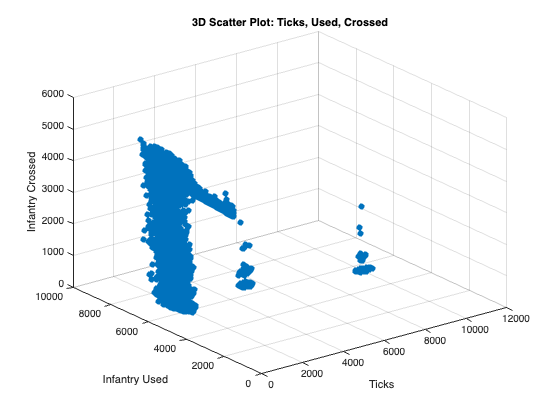


%% FIGURE 21: 3D Scatter Plot - Ticks, Infantry Used, and Infantry Crossed
figure;
scatter3(data.ticks, data.total_infantry_used, data.total_infantry_crossed, 36, 'filled');
xlabel('Ticks');
ylabel('Infantry Used');
zlabel('Infantry Crossed');
title('3D Scatter Plot: Ticks, Used, Crossed');
grid on;

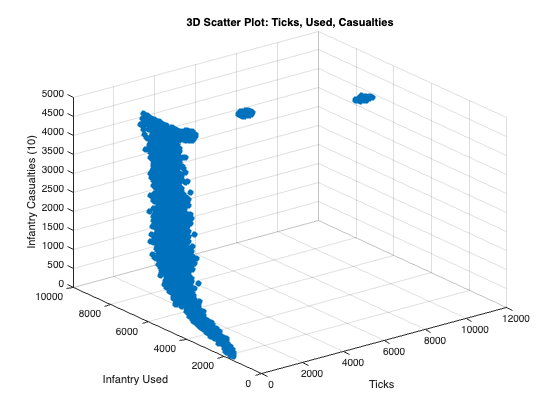


%% FIGURE 22: 3D Scatter Plot - Ticks, Infantry Used, and Infantry Casualties (10)
figure;
scatter3(data.ticks, data.total_infantry_used, data.total_infantry_casualties_10, 36, 'filled');
xlabel('Ticks');
ylabel('Infantry Used');
zlabel('Infantry Casualties (10)');
title('3D Scatter Plot: Ticks, Used, Casualties');
grid on;

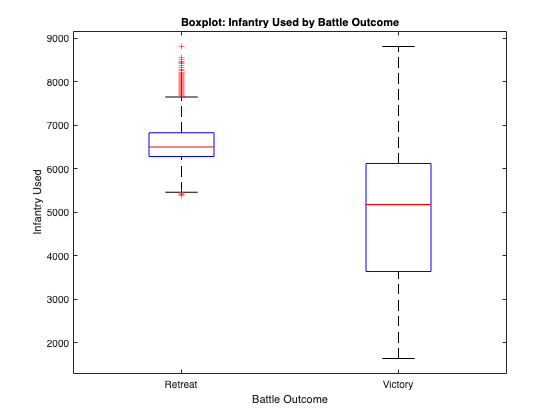


%% FIGURE 23: Boxplot of Infantry Used by Battle Outcome
figure;
boxplot(data.total_infantry_used, data.battle_outcome);
xlabel('Battle Outcome');
ylabel('Infantry Used');
title('Boxplot: Infantry Used by Battle Outcome');

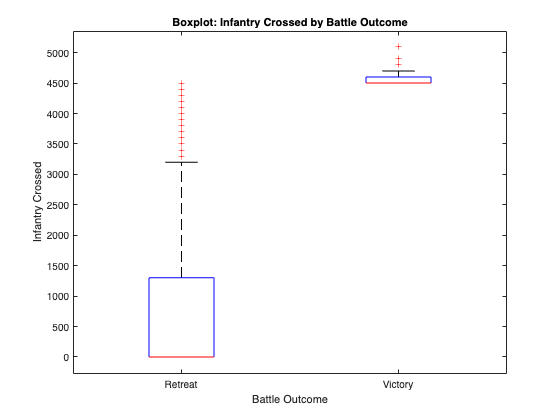


%% FIGURE 24: Boxplot of Infantry Crossed by Battle Outcome
figure;
boxplot(data.total_infantry_crossed, data.battle_outcome);
xlabel('Battle Outcome');
ylabel('Infantry Crossed');
title('Boxplot: Infantry Crossed by Battle Outcome');

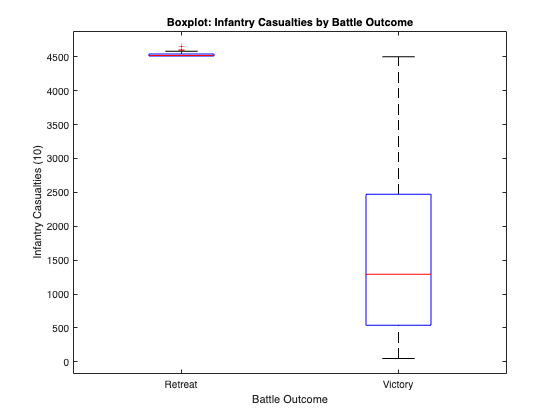


%% FIGURE 25: Boxplot of Infantry Casualties (10) by Battle Outcome
figure;
boxplot(data.total_infantry_casualties_10, data.battle_outcome);
xlabel('Battle Outcome');
ylabel('Infantry Casualties (10)');
title('Boxplot: Infantry Casualties by Battle Outcome');

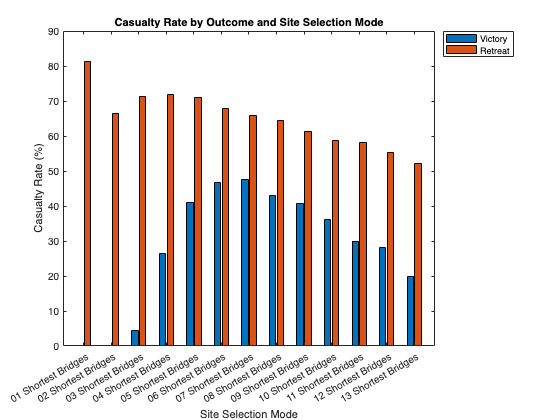


%% FIGURE 26: Grouped Bar Chart - Casualty Rate by Outcome and Site Selection Mode
% For each site mode, calculate casualty rate for Victory and Retreat separately.
casualtyRatesOutcome = zeros(length(siteModes), 2);  % Column 1: Victory, Column 2: Retreat
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    % For Victory
    idxV = idx & strcmp(data.battle_outcome, 'Victory');
    if sum(idxV) > 0
        casualtyRatesOutcome(i,1) = sum(data.total_infantry_casualties_10(idxV)) / sum(data.total_infantry_used(idxV)) * 100;
    else
        casualtyRatesOutcome(i,1) = NaN;
    end
    % For Retreat
    idxR = idx & strcmp(data.battle_outcome, 'Retreat');
    if sum(idxR) > 0
        casualtyRatesOutcome(i,2) = sum(data.total_infantry_casualties_10(idxR)) / sum(data.total_infantry_used(idxR)) * 100;
    else
        casualtyRatesOutcome(i,2) = NaN;
    end
end
figure;
bar(categorical(siteModes), casualtyRatesOutcome);
xlabel('Site Selection Mode');
ylabel('Casualty Rate (%)');
legend({'Victory','Retreat'}, 'Location', 'bestoutside');
title('Casualty Rate by Outcome and Site Selection Mode');

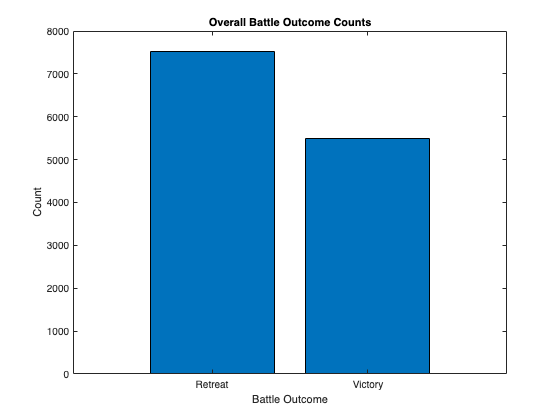


%% FIGURE 27: Bar Chart of Overall Battle Outcome Counts
figure;
overallCounts = zeros(length(battleOutcomes), 1);
for i = 1:length(battleOutcomes)
    overallCounts(i) = sum(strcmp(data.battle_outcome, battleOutcomes{i}));
end
bar(categorical(battleOutcomes), overallCounts);
xlabel('Battle Outcome');
ylabel('Count');
title('Overall Battle Outcome Counts');

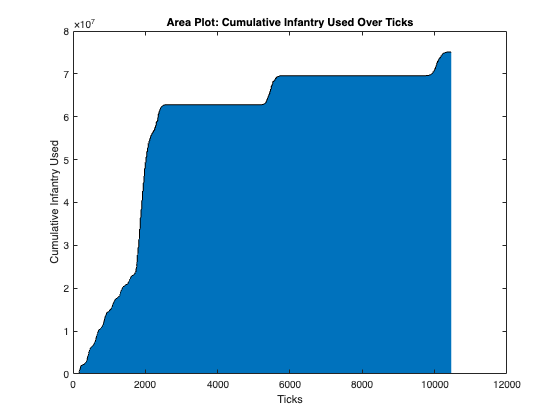


%% FIGURE 28: Area Plot of Cumulative Infantry Used Over Ticks
figure;
area(sortedTicks, cumUsed);
xlabel('Ticks');
ylabel('Cumulative Infantry Used');
title('Area Plot: Cumulative Infantry Used Over Ticks');

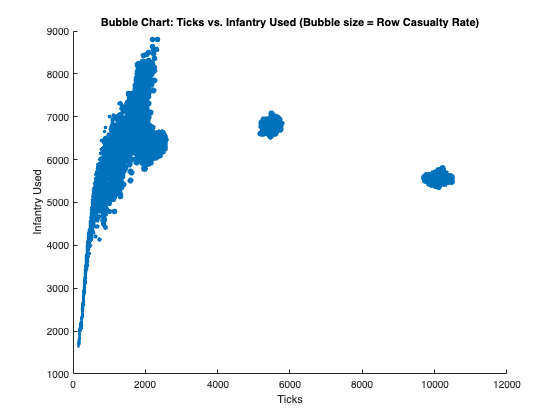


%% FIGURE 29: Bubble Chart - Ticks vs. Infantry Used
% Bubble size is proportional to the row-wise casualty rate.
m = max(rowCasualtyRate(~isnan(rowCasualtyRate) & rowCasualtyRate > 0));
if isempty(m)
    m = 1;
end
bubbleSizes3 = 50 * (rowCasualtyRate ./ m);
bubbleSizes3(bubbleSizes3 <= 0) = 1;  % Ensure bubble sizes are positive.
figure;
scatter(data.ticks, data.total_infantry_used, bubbleSizes3, 'filled');
xlabel('Ticks');
ylabel('Infantry Used');
title('Bubble Chart: Ticks vs. Infantry Used (Bubble size = Row Casualty Rate)');

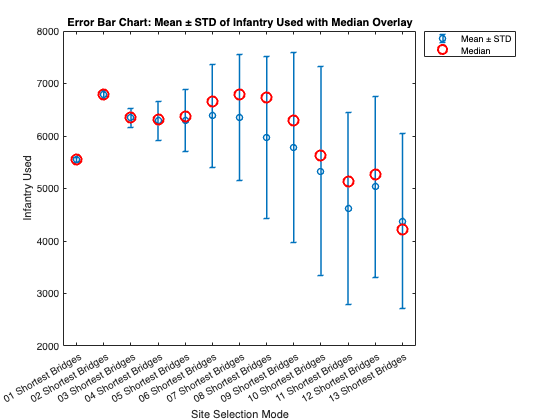


%% FIGURE 30: Error Bar Chart - Mean and STD of Infantry Used with Median Overlay
meanUsedByMode = zeros(length(siteModes),1);
stdUsedByMode = zeros(length(siteModes),1);
medianUsedByMode = zeros(length(siteModes),1);
for i = 1:length(siteModes)
    idx = strcmp(data.site_selection_mode, siteModes{i});
    meanUsedByMode(i) = mean(data.total_infantry_used(idx));
    stdUsedByMode(i) = std(data.total_infantry_used(idx));
    medianUsedByMode(i) = median(data.total_infantry_used(idx));
end
figure;
errorbar(categorical(siteModes), meanUsedByMode, stdUsedByMode, 'o', 'LineWidth', 1.5);
hold on;
plot(categorical(siteModes), medianUsedByMode, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Site Selection Mode');
ylabel('Infantry Used');
title('Error Bar Chart: Mean ± STD of Infantry Used with Median Overlay');
legend({'Mean ± STD','Median'}, 'Location', 'bestoutside');
hold off;